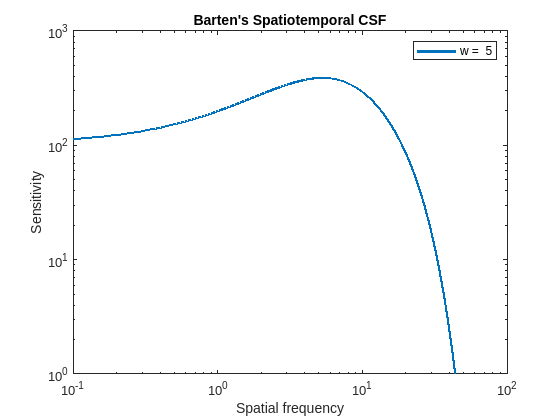

clear;
close all;
clc;

% Spatial frequency range in cpd
u         = 0.1:0.01:100;

% Temporal frequency range in HZ
w         = 5;

% Eccentricity in degrees
e         = 0;

% Average luminance of the observed object in cd/m^2
L         = 100;

% Field diameter in degrees
D         = 2.5;

% Signal to Noise ratio
k         = 3;

% Constant for quantom efficiency
eta0      = 0.03;

% constanct for the eye MTF
sigma0    = 0.5;

% eccentricity constant (can be different for various subjects)
eg        = 3.3;

% Spatial frequency above which the lateral inhibition ceases as a function of eccentricity in Fovea
u00       = 7;

% Specify the viewing mode
view_mode = "binocular";

stBarCSF  = stModifiedBarten(u,w,e,L,D,k,eta0,sigma0,eg,u00,view_mode);

figure;
loglog(u,stBarCSF, LineWidth=2);
title("Barten's Spatiotemporal CSF")
ylim([1 1000]);
xlim([0.1 100]);
ylabel("Sensitivity")
xlabel("Spatial frequency")
legendCell = cellstr(num2str(w, 'w =  %-d'));
legend(legendCell)